a = 1;
b = 0;
c = -1;
d = -2;
e = 0;
f = 1;
B = [a b/2; b/2 c]

B =      1     0
     0    -1


[e_vec,e_num] = eig(B)

e_vec =      0     1
     1     0


e_num =     -1     0
     0     1



if e_num(1,1)>0 && e_num(2,2)>0 
    text = "Эллипс"
    k=0
end
if (e_num(1,1)>0 && e_num(2,2)<0) || (e_num(1,1)<0 && e_num(2,2)>0)
    if det([a b/2 d/2;
            b/2 c e/2; 
            d/2 e/2 f])==0
    
   
        text = "Пара пересекающихся прямых"
        k=3;
   
    else
    text = "Гипербола"
    k = 0
    end
end

text = "Пара пересекающихся прямых"

if (e_num(1,1)==0 && e_num(2,2)~=0) || (e_num(1,1)~=0 && e_num(2,2)==0)
    if det([a b/2 d/2;
            b/2 c e/2; 
            d/2 e/2 f])==0 && (det([a d/2; d/2 f])+det([c e/2; e/2 f]))<0
        text = "Пара параллельных прямых"
        k=2;
    else
    text = "Парабола"
    k = 1
    end
end
norm1 = sqrt(e_vec(1,1)^2+e_vec(2,1)^2)

norm1 = 1

new_i = [e_vec(1,1)/norm1; e_vec(2,1)/norm1]

new_i =      0
     1


% norm2 = sqrt(e_vec(1,2)^2+e_vec(2,2)^2)
% new_j = [e_vec(1,2)/norm2; e_vec(2,2)/norm2]

syms x y x1 y1 x2 y2 xf yf x3 y3 xt yt t

X1Y1=[x1;y1]

$$X1Y1 = \left(\begin{array}{c} x_{1}\\ y_{1} \end{array}\right)$$

XY = e_vec*X1Y1

$$XY = \left(\begin{array}{c} y_{1}\\ x_{1} \end{array}\right)$$

x = XY(1)

$$x = y_{1}$$

y = XY(2)

$$y = x_{1}$$

f_original = a*xf^2 +b*xf*yf + c*yf^2 +d*xf + e*yf + f

$$f\_original = {\mathrm{xf}}^{2}-2\,\mathrm{xf}-{\mathrm{yf}}^{2}+1$$

f_first = a*x^2 +b*x*y + c*y^2 +d*x + e*y + f

$$f\_first = -{x_{1}}^{2}+{y_{1}}^{2}-2\,y_{1}+1$$

f_new = simplify(f_first)

$$f\_new = -{x_{1}}^{2}+{y_{1}}^{2}-2\,y_{1}+1$$

orig = fimplicit(f_original, [-10 10 -10 10])

orig =   ImplicitFunctionLine with properties:

     Function: [1×1 sym]
       XRange: [-10 10]
       YRange: [-10 10]
        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 0.5000

  Show all properties



hold on
cxy = coeffs(f_new, [x1 y1])

$$cxy = \left(\begin{array}{cccc} 1 & -2 & 1 & -1 \end{array}\right)$$

if (length(cxy)==5) 
     f_2=-1*((x3+(cxy(4)/(2*cxy(5))))^(2)/((cxy(1)-((cxy(4))^2)/(4*cxy(5))-((cxy(2))^2)/(4*cxy(3)))/cxy(5))+(y3+(cxy(2)/(2*cxy(3))))^(2)/((cxy(1)-((cxy(4))^2)/(4*cxy(5))-((cxy(2))^2)/(4*cxy(3)))/cxy(3)))
      f_3=(cxy(1)-((cxy(4))^2)/(4*cxy(5))-((cxy(2))^2)/(4*cxy(3)))/(cxy(1)-((cxy(4))^2)/(4*cxy(5))-((cxy(2))^2)/(4*cxy(3)))
      xC=-(x+(cxy(4)/(2*cxy(5))))
      yC = (y+(cxy(2)/(2*cxy(3))))
      D = solve([xC==0 yC==0],x1,y1)
      R = [D.x1, D.y1]
      
      plot(D.x1,D.y1, "ro")
      
      
      line([D.x1 D.x1+10*e_vec(1,1)], [D.y1 D.y1+10*e_vec(2,1)], "color", "r")
      line([D.x1 D.x1-10*e_vec(1,1)], [D.y1 D.y1-10*e_vec(2,1)], "color", "r")
      line([D.x1 D.x1+10*e_vec(1,2)], [D.y1 D.y1+10*e_vec(2,2)], "color", "r")
      line([D.x1 D.x1-10*e_vec(1,2)], [D.y1 D.y1-10*e_vec(2,2)], "color", "r")


end
if (length(cxy)==4) && f==0 
     f_2=((x3+(cxy(3)/2*cxy(4)))^2/cxy(2))+((y3+(cxy(1)/2*cxy(2)))^2/cxy(4))
     f_3= (((cxy(3))^2*cxy(2))+((cxy(1))^2*cxy(4)))/(4*(cxy(4)*cxy(2))^2)
      xC= x+(cxy(3)/(2*cxy(4)))
      yC = y+(cxy(1)/(2*cxy(2)))
       
      D = solve([xC==0 yC==0],x1,y1)
      R = [D.x1, D.y1]
      
      plot(D.x1,D.y1, "ro")
      
      
      line([D.x1 D.x1+10*e_vec(1,1)], [D.y1 D.y1+10*e_vec(2,1)], "color", "r")
      line([D.x1 D.x1-10*e_vec(1,1)], [D.y1 D.y1-10*e_vec(2,1)], "color", "r")
      line([D.x1 D.x1+10*e_vec(1,2)], [D.y1 D.y1+10*e_vec(2,2)], "color", "r")
      line([D.x1 D.x1-10*e_vec(1,2)], [D.y1 D.y1-10*e_vec(2,2)], "color", "r")

end

if (length(cxy)==4) && k ==1 
    if c ~= 0
    f_2=(y3+cxy(2)/(2*cxy(3)))^2-(cxy(2)^2)/(4*cxy(3))+cxy(4)*(x3+cxy(1)/cxy(4))
    f_3 = 0
    
    xC = -(-(cxy(2)^2)/(4*cxy(3))+cxy(4)*(x+cxy(1)/cxy(4)))
    yC = y+cxy(2)/(2*cxy(3))
    D = solve([xC==0 yC==0],x1,y1)
    R = [D.x1, D.y1]
    plot(D.x1,D.y1, "ro")
    line([D.x1 D.x1+10*e_vec(1,1)], [D.y1 D.y1+10*e_vec(2,1)], "color", "r")
    line([D.x1 D.x1-10*e_vec(1,1)], [D.y1 D.y1-10*e_vec(2,1)], "color", "r")
    line([D.x1 D.x1+10*e_vec(1,2)], [D.y1 D.y1+10*e_vec(2,2)], "color", "r")
    line([D.x1 D.x1-10*e_vec(1,2)], [D.y1 D.y1-10*e_vec(2,2)], "color", "r");
    
    elseif (a ~= 0)
    f_2=(x3+cxy(2)/(2*cxy(3)))^2-(cxy(2)^2)/(4*cxy(3))+cxy(4)*(y3+cxy(1)/cxy(4))
    f_3 = 0
    
    xC = -(-(cxy(2)^2)/(4*cxy(3))+cxy(4)*(x+cxy(1)/cxy(4)))
    yC = y+cxy(2)/(2*cxy(3))
     D = solve([xC==0 yC==0],x1,y1)
      R = [D.x1, D.y1]
      
      plot(D.x1,D.y1, "ro")
      
      line([D.x1 D.x1+10*e_vec(1,1)], [D.y1 D.y1+10*e_vec(2,1)], "color", "r")
      line([D.x1 D.x1-10*e_vec(1,1)], [D.y1 D.y1-10*e_vec(2,1)], "color", "r")
      line([D.x1 D.x1+10*e_vec(1,2)], [D.y1 D.y1+10*e_vec(2,2)], "color", "r")
      line([D.x1 D.x1-10*e_vec(1,2)], [D.y1 D.y1-10*e_vec(2,2)], "color", "r")

    end
end
 if (length(cxy)==3) && d ==0 && e == 0
    f_2=((x3^2)/cxy(2))+ ((y3^2)/cxy(3))
    f_3 = -cxy(1)/cxy(2)*cxy(3)
    
    xC = x
    yC = y
    D = solve([xC==0 yC==0],x1,y1)
    R = [D.x1, D.y1]
    plot(D.x1,D.y1, "ro")
    line([D.x1 D.x1+10*e_vec(1,1)], [D.y1 D.y1+10*e_vec(2,1)], "color", "r")
    line([D.x1 D.x1-10*e_vec(1,1)], [D.y1 D.y1-10*e_vec(2,1)], "color", "r")
    line([D.x1 D.x1+10*e_vec(1,2)], [D.y1 D.y1+10*e_vec(2,2)], "color", "r")
    line([D.x1 D.x1-10*e_vec(1,2)], [D.y1 D.y1-10*e_vec(2,2)], "color", "r")
end

if (length(cxy) == 2) && (k == 1)
   cxy = [cxy 0 ]
   f_2=((x3^2)/cxy(2))+ ((y3^2)/cxy(3))
    f_3 = -cxy(1)/cxy(2)*cxy(3)
    
    xC = x
    yC = y
    D = solve([xC==0 yC==0],x1,y1)
    R = [D.x1, D.y1]
    plot(D.x1,D.y1, "ro")
    line([D.x1 D.x1+10*e_vec(1,1)], [D.y1 D.y1+10*e_vec(2,1)], "color", "r")
    line([D.x1 D.x1-10*e_vec(1,1)], [D.y1 D.y1-10*e_vec(2,1)], "color", "r")
    line([D.x1 D.x1+10*e_vec(1,2)], [D.y1 D.y1+10*e_vec(2,2)], "color", "r")
    line([D.x1 D.x1-10*e_vec(1,2)], [D.y1 D.y1-10*e_vec(2,2)], "color", "r")
end
if (length(cxy)==3) && (k==2)
    if a == 0
    f_2=(((y3^2)+(cxy(2))/(2*cxy(3))))/((cxy(2))^2/((4*(cxy(3))^2)-cxy(1)/cxy(3)))
    f_3 = 1
    xC = x;
    yC = (((y^2)+(cxy(2))/(2*cxy(3))))/((cxy(2)))
    
    end
    if c == 0
    f_2=(((x3^2)+(cxy(2))/(2*cxy(3))))/((cxy(2))^2/((4*(cxy(3))^2)-cxy(1)/cxy(3)))
    f_3 = 1
    xC = (((x3^2)+(cxy(2))/(2*cxy(3))))/((cxy(2)))
    yC = y3
    end
    D = solve([xC==0,yC ==0 ],x1,y1)
    R = [D.x1, D.y1]
    plot(D.x1,D.y1, "ro")
    line([D.x1 D.x1+10*e_vec(1,1)], [D.y1 D.y1+10*e_vec(2,1)], "color", "r")
    line([D.x1 D.x1-10*e_vec(1,1)], [D.y1 D.y1-10*e_vec(2,1)], "color", "r")
    line([D.x1 D.x1+10*e_vec(1,2)], [D.y1 D.y1+10*e_vec(2,2)], "color", "r")
    line([D.x1 D.x1-10*e_vec(1,2)], [D.y1 D.y1-10*e_vec(2,2)], "color", "r")
end

 text = "Центр в точке" ,R

text = "Центр в точке"

$$R = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

 

trr1 = e_vec(:,1) + e_vec(:,2) 

trr1 =      1
     1



basis = [1 0; 
         0 1]

basis =      1     0
     0     1



% X

aa= e_vec

aa =      0     1
     1     0



R

$$R = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

 Text = char(R)

Text = '[0, 0]'

 e_vec_new = (e_vec(:,1))'

e_vec_new =      0     1


                 vectors.Text = string(e_vec_new)

vectors = struct with fields:
    Text: ["0"    "1"]


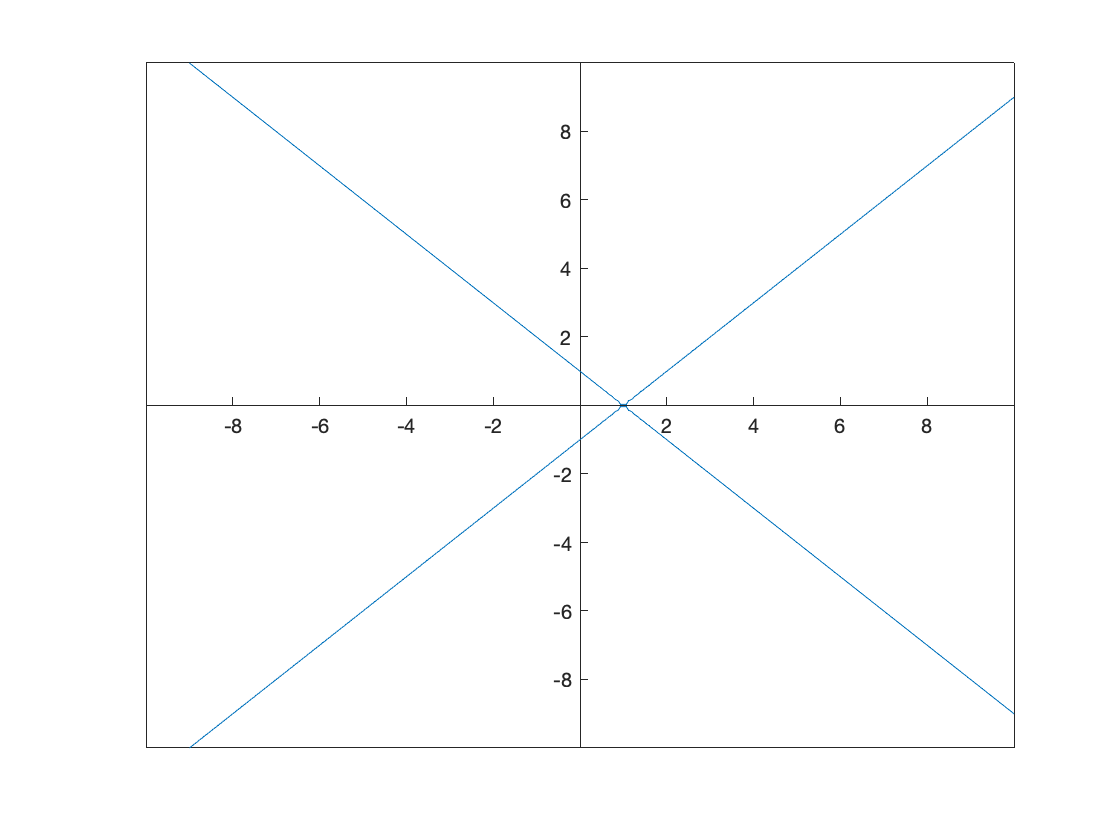

                 



%fimplicit(xC)
% p.LineColor = "r";
%fimplicit(yC)

set(gca, 'XAxisLocation', 'origin')
set(gca, 'YAxisLocation', 'origin')